function [Instrument, Node, udpPortArray, ind, Localhost_publicIP] = Connection_Instrument(instrList, Timeout, instrInfo, udpPortArray, ConnectionType, RootFolder, ResetCommand, SyncType)

    Type     = instrList.Type{1};
    IP       = instrList.IP{1};
    Port     = str2double(instrList.Port{1});
    inBuffer = instrList.inBuffer(1);
    
    Instrument = [];
    Node       = '';
    ind        = [];
    Localhost_publicIP = '';
    
    instrreset
    pause(1)
    switch Type
        case {'TCPIP Socket', 'Visa TCPIP', 'TCP/UDP IP Socket'}
            if strcmp(Type, 'Visa TCPIP'); Instrument = visa('ni', ['TCPIP0::' IP '::inst0::INSTR']); 
            else;                          Instrument = tcpip(IP, Port);
            end
            
            set(Instrument, 'Timeout', Timeout, 'InputBufferSize', inBuffer*1e+6, 'ByteOrder', 'littleEndian');
            fopen(Instrument);
            
            Node = Misc_Hostname('General', Instrument);
            
        case 'NCPIP Socket'
            % Enquanto não estudo a biblioteca matlab_ncp_lib.dll...
            Node = Misc_Hostname('RFeye', instrList(1,:), RootFolder);
    end
    
    if contains(ConnectionType, 'Task')
        instrInd = find(strcmp(instrInfo.Name, instrList.Name{1}), 1);

        if strcmp(ResetCommand, 'On')
            fprintf(Instrument, instrInfo.scpiReset{instrInd});
            pause(instrInfo.ResetPause{instrInd})
        end
        
        fprintf(Instrument, instrInfo.StartUp{instrInd});
        
        switch SyncType
            case 'Single Sweep';     fprintf(Instrument, 'INITiate:CONTinuous OFF');
            case 'Continuous Sweep'; fprintf(Instrument, 'INITiate:CONTinuous ON');
            case 'Streaming'
        end

        switch instrInfo.connectFlag{instrInd}
            case 1
                % Analisadores de espectro
                
            case 2
                % EB500
                if ~isempty(instrList.Localhost_localIP{1})
                    Localhost_localIP = instrList.Localhost_localIP{1};
                    if ~isempty(instrList.Localhost_publicIP); Localhost_publicIP = instrList.Localhost_publicIP{1};
                    else;                                      Localhost_publicIP = Localhost_localIP;
                    end
                else
                    [~, Localhost_publicIP] = Misc_ClientIPs(IP);
                end
                
                [udpPortArray, ind] = Connection_udpLogger(udpPortArray, 24001, Timeout);
        end
    end

end

## Função auxiliar 1: Hostname

function Node = Misc_Hostname(arg1, arg2, arg3)

    Node = '';
    switch arg1
        case 'General'
            Node = deblank(query(arg2, '*IDN?'));
            Node = replace(Node, '"', '');
            
        case 'RFeye'
            Credentials = jsondecode(arg2.Description{1});
            
            for ii = 1:numel(Credentials(1).Password)
                try
                    webmsg = webread(sprintf('http://%s/apps/logger/log/status/', arg2.IP{1}), weboptions('Username', Credentials(1).Username,'Password', Credentials(1).Password{ii}));
                    Node   = char(regexp(webmsg,'(?<=<td>)rfeye\d{6}(?=</td>)', 'match', 'ignorecase'));
                catch
                end
            end
            
            if ~isempty(Node)
                return
            else
                for ii = 1:numel(Credentials(2).Password)
                    try
                        ftpObj = ftp(arg2.IP{1}, Credentials(2).Username, Credentials(2).Password{ii});
                        
                        cd(ftpObj, '/etc/node/')
                        mget(ftpObj, 'net.cfg', fullfile(arg3, 'Temp'))
                        
                        filemsg = fileread('net.cfg');
                        Node    = char(regexp(filemsg,'rfeye\d{6}', 'match', 'ignorecase'));
                    catch
                    end
                end
            end
    end
        
    if isempty(Node); error('EmptyName')
    end
    
end

## Função auxiliar 2: Local e public IPs

Conforme apresentada nas imagens abaixo (Windows em diversos idiomas), o *template* da resposta ao comando do sistema "arp -a" possui os caracteres " --- " nas linhas em que constam os endereços de IP do cliente.

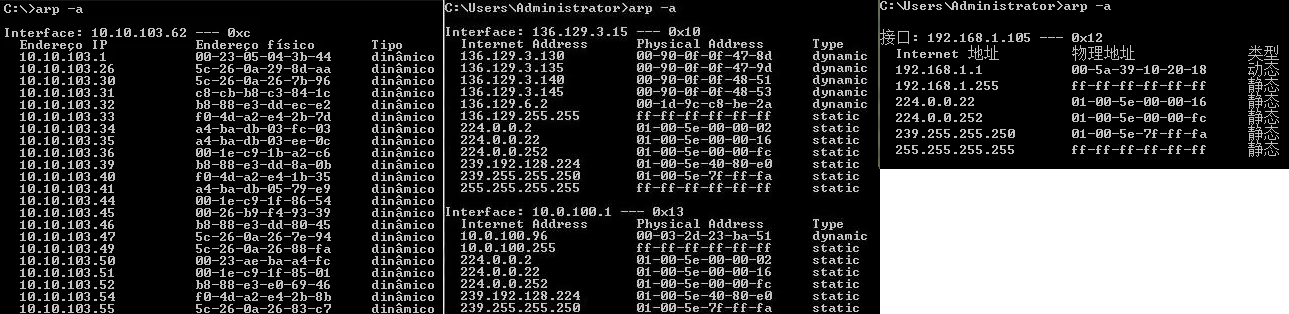

function [localIP, publicIP] = Misc_ClientIPs(instrIP)

    [~, msg] = system('arp -a');

    msgCell  = strsplit(msg, newline)';
    
    indEmpty = cellfun(@(x) isempty(x), msgCell);
    msgCell(indEmpty) = [];
    
    ind_localIPs = find(cellfun(@(x) contains(x, ' --- '), msgCell));
    ind_instrIPs = find(cellfun(@(x) contains(x, [' ' instrIP ' ']), msgCell));
    
    localIP = '';
    if ~isempty(ind_instrIPs)
        ind_instrIPs = ind_instrIPs(1);
        
        temp = ind_localIPs - ind_instrIPs;
        ind  = find(temp<0);
        ind  = ind(end);
                
        localIP  = char(regexp(msgCell{ind_localIPs(ind)}, '(\d{1,3}.\d{1,3}.\d{1,3}.\d{1,3})', 'match'));
        publicIP = localIP;
        
    else
        localIPs = {};
        for ii = 1:numel(ind_localIPs)
            localIPs = [localIPs, regexp(msgCell{ind_localIPs(ii)}, '(\d{1,3}.\d{1,3}.\d{1,3}.\d{1,3})', 'match')];
        end
        
        for jj = 1:numel(localIPs)
            if ~system(sprintf('ping -n 3 -w 1000 -S %s %s', localIPs{jj}, instrIP))
                localIP = localIPs{jj};
                break
            end
        end
        
        publicIP = char(regexp(webread('http://checkip.dyndns.org'), '(\d{1,3}.\d{1,3}.\d{1,3}.\d{1,3})', 'match'));
    end

end